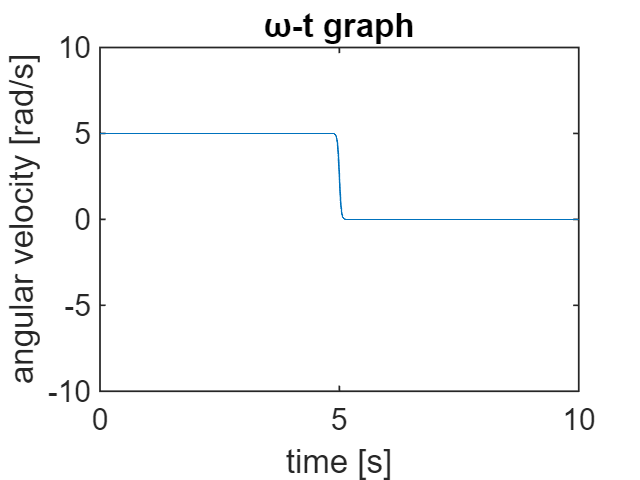

clear;
% initialize
h = 0.001; %step size (time)
Simulation_time = 10; %[s]
T = 0; %array position
s = 50; %steepness factor
A = 5; % Amplitude/ max value of angular velocity
t = zeros(10000,1);
a = zeros(10000,1);
w = zeros(10000,1);
p = zeros(10000,1);
e_minus = zeros(10000,1);
e_plus = zeros(10000,1);
for i = 0:h:Simulation_time 
    T = T+1;
    t(T) = i;
    %exponential functions used in kinematic functions
    e_minus(T,1) = exp(-s*(t(T,1)-5));
    e_plus(T,1) = exp(s*(t(T,1)-5));
    % angular velocity
    % continious variant of the Heaviside step function
    % otherwise known as the sigmoid function
    w(T,1) = A-A/(1+e_minus(T,1));
    % position (angular)
    p(T,1) = A*(t(T,1))-(A/s)*(log((e_plus(T,1)+1)/2));
    % angular accelaration
    a(T,1) = -(A*s*e_minus(T,1))/((1+(e_minus(T,1)))^2);
end


w;
a;
% time-angular velocity graph
figure(1);
plot(t,w)
xlim([0 10])
ylim([-10 10])
title('ω-t graph');
xlabel('time [s]') ;
ylabel('angular velocity [rad/s]') ;

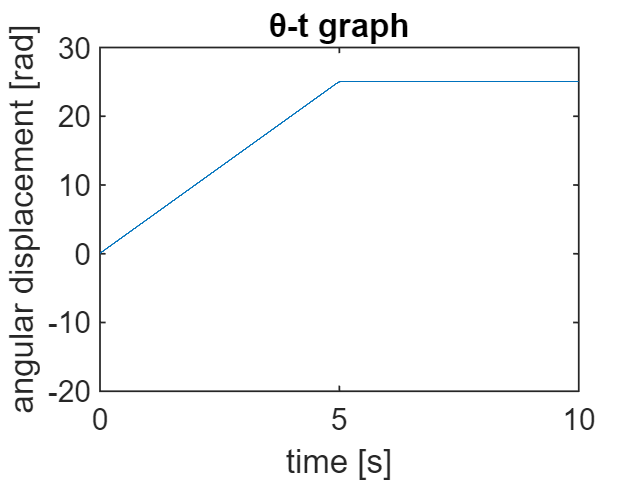


%time-angular displacement
figure(2);
plot(t,p);
xlim([-10 10]);
ylim([-20 30]);
title('θ-t graph');
xlabel('time [s]');
ylabel('angular displacement [rad]'); 

xlim([0 10.0]);
ylim([-20 30]);

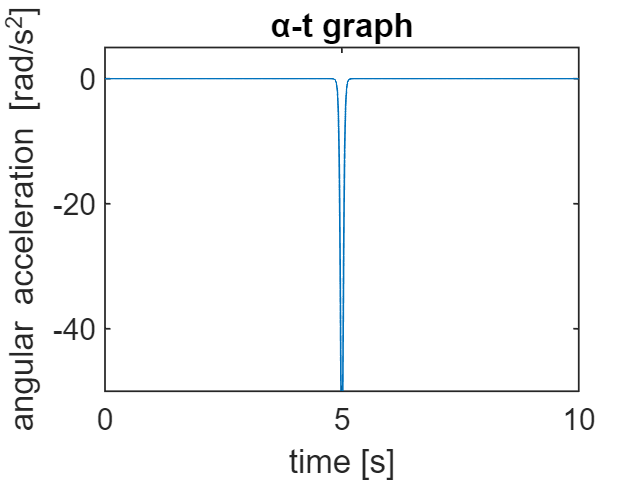

%time-angular acceleration graph
figure(3);
plot(t,a);
title('α-t graph');
xlabel('time [s]');
ylabel('angular acceleration [rad/s^2]'); 
xlim([0 10])
ylim([-50 5])


% generate Simulation variables into workspace
theta = timeseries(p, t)

  timeseries

  Common Properties:
            Name: 'unnamed'
            Time: [10001x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [10001x1 double]
        DataInfo: 

omega = timeseries(w,t)

  timeseries

  Common Properties:
            Name: 'unnamed'
            Time: [10001x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [10001x1 double]
        DataInfo: 

alpha = timeseries(a,t)

  timeseries

  Common Properties:
            Name: 'unnamed'
            Time: [10001x1 double]
        TimeInfo: [1x1 tsdata.timemetadata]
            Data: [10001x1 double]
        DataInfo: 